# **OFDM System**

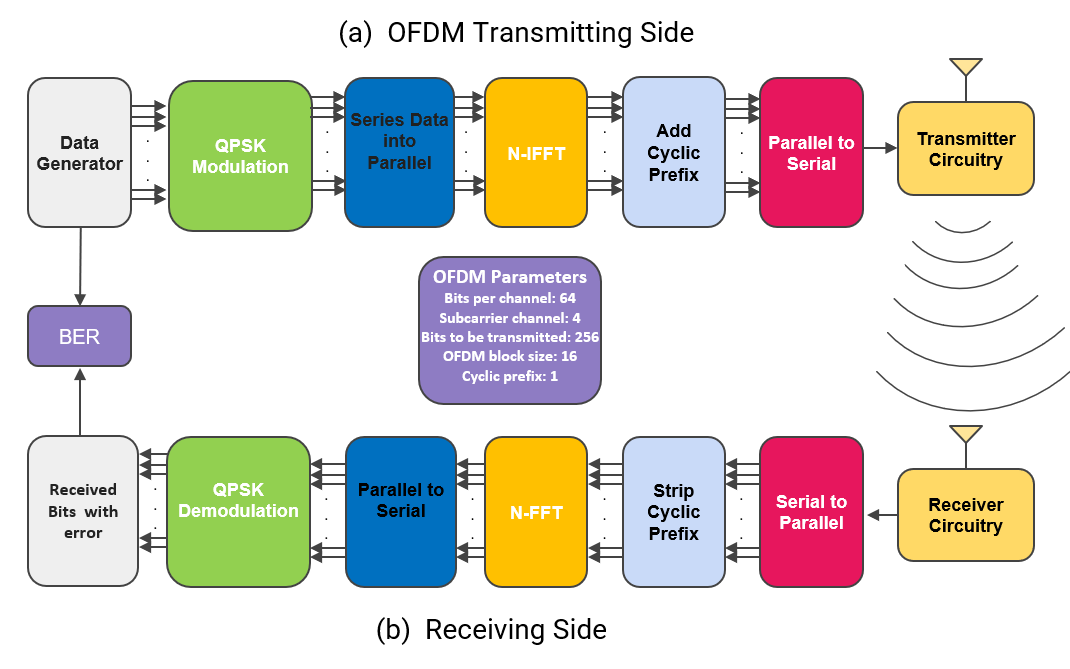

OFDM (Orthogonal Frequency Division Multiplexing) is a digital communication technique used to transmit a high data rate signal over a wireless network. It uses multiple subcarriers, each carrying a different part of the signal, to transmit the data in parallel. This allows for higher data rates and more reliable signal transmission than single-carrier systems. The MATLAB code replicates the basic chain of an OFDM transmitter and receiver, which includes modulating and demodulating the signal, and adding and removing cyclic prefixes. This code can be used to analyze the performance of OFDM systems, test communications algorithms, and evaluate hardware implementations. It is also a useful tool for teaching students the fundamentals of OFDM.

# **Part A: Transmiter**

## Step 1: OFDM Transmitting Side

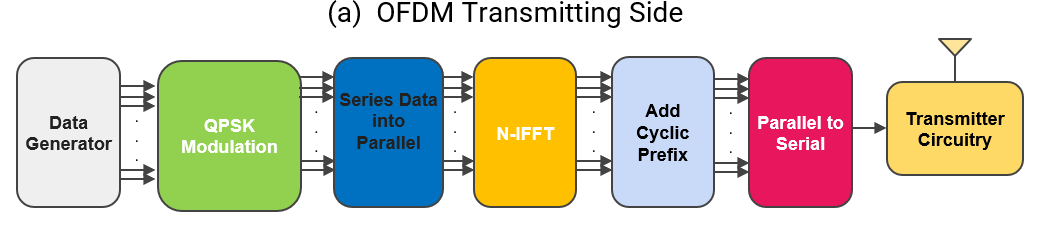

clc;
clear all
close all

## Step 2: Define transmitter properties 

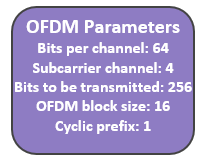

The total number of bits to be transmitted (n) is equal to the number of data bits per channel (64) multiplied by the number of subcarrier channels (4). Thus, n = 64 × 4 = 256. The size of each OFDM block is 16, so the length of the cyclic prefix is calculated as 0.1 x 16 = 1.6, which is rounded down to 1. Therefore, the total number of bits to be transmitted is 256, and the size of each OFDM block is 16 with a cyclic prefix length of 1.

no_of_data_bits = 64;                %Number of bits per channel 
M =4;                                %Number of subcarrier channel
n=M*no_of_data_bits;                 %Total number of bits to be transmitted                    
block_size = 16;                     %Size of each OFDM block to add cyclic prefix
cp_len = floor(0.1 * block_size);    %Length of the cyclic prefix

## Step 3: Generate random data source to be transmitted of length 64

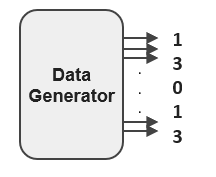

This code generates a set of random numbers between 0 and M-1 and plots them on a graph. The first parameter in the randsrc function defines the number of rows in the output matrix, and the second parameter defines the number of columns. The third parameter is the range of numbers to randomly sample from, which in this case is between 0 and M-1. The stem command is used to plot the data points, with the x-axis representing the data points and the y-axis representing the amplitude. The grid is turned on and labels are added for both the x-axis and y-axis. A title is also added for the plot.

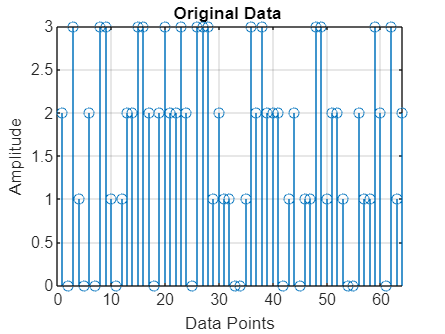

data = randsrc(1, no_of_data_bits, 0:M-1);stem(data); grid on; xlabel('Data Points'); ylabel('Amplitude');title('Original Data ')

## Step 4: Perform QPSK modulation on the input source data

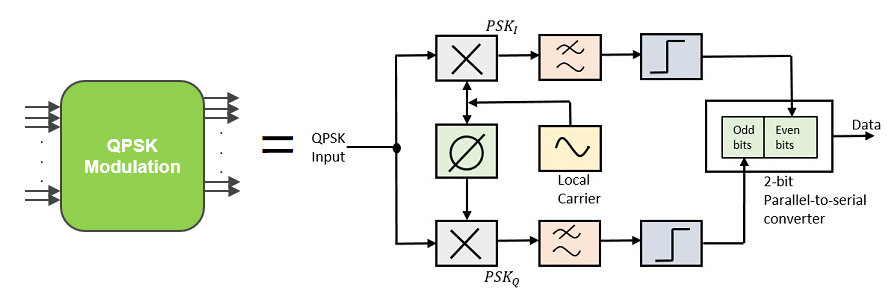

This code is used to modulate a signal using Quadrature Phase Shift Keying (QPSK). QPSK is a type of digital modulation technique in which two binary bits are assigned to each symbol. The code takes in the data to be modulated as the first argument and the number of bits per symbol as the second argument. In this case, the signal is being modulated with M bits per symbol. The output of the code is a stream of modulated data that can be visualized as a signal on a stem plot.

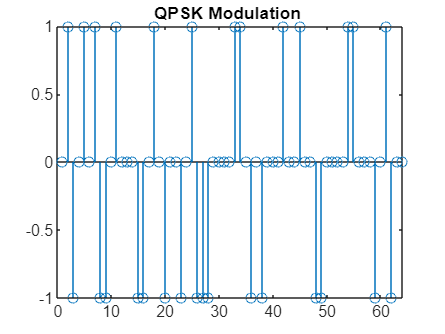

qpsk_modulated_data = pskmod(data, M);stem(qpsk_modulated_data);title('QPSK Modulation ')

## Step 5: Converting the series data  into parallel data 

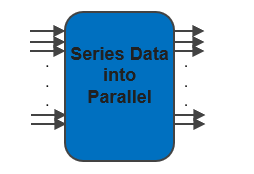

This code is used to form sub carriers from a QPSK modulated data. The data is reshaped into a matrix with the number of rows being equal to the number of data bits divided by M (the number of sub-carriers). Each column of the matrix represents a single sub-carrier. The code then plots the real part of each sub-carrier on a separate subplot.


S2P = reshape(qpsk_modulated_data, no_of_data_bits/M,M);
Sub_carrier1 = S2P(:,1)

Sub_carrier1 =   -0.0000 - 1.0000i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i
   0.0000 + 1.0000i


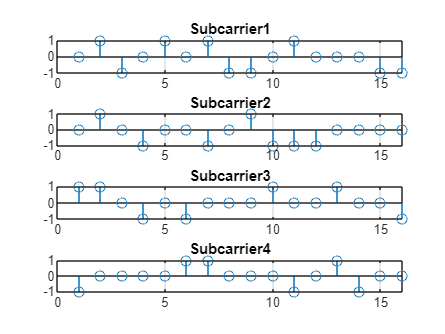

Sub_carrier2 = S2P(:,2);
Sub_carrier3 = S2P(:,3);
Sub_carrier4 = S2P(:,4);

subplot(4,1,1),stem(real(Sub_carrier1)),title('Subcarrier1'),grid on
subplot(4,1,2),stem(real(Sub_carrier2)),title('Subcarrier2'),grid on;
subplot(4,1,3),stem(real(Sub_carrier3)),title('Subcarrier3'),grid on;
subplot(4,1,4),stem(real(Sub_carrier4)),title('Subcarrier4'),grid on;

## Step 6: IFFT OF SUB_CARRIERS

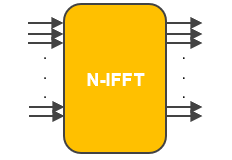

This code is performing an Inverse Fast Fourier Transform (IFFT) on four sub-carriers. An IFFT is the inverse of a Fast Fourier Transform (FFT) and converts a signal from the frequency domain back into the time domain. By performing an IFFT on the four sub-carriers, we can visualise the signal in the time domain. The number of sub-carriers is specified by the variable M, and the block size and cyclic prefix length are specified by the variables block_size and cp_len respectively. The code then plots the IFFT of each sub-carrier in a 4x1 subplot.

number_of_subcarriers=M;
cp_start=block_size-cp_len;
ifft_Subcarrier1 = ifft(Sub_carrier1)

ifft_Subcarrier1 =   -0.0625 - 0.0625i
  -0.0951 - 0.0338i
  -0.3902 + 0.1768i
   0.3834 - 0.0912i
   0.1875 + 0.0625i
   0.2106 + 0.0817i
  -0.3018 + 0.0884i
  -0.0856 - 0.0433i
   0.0625 - 0.1875i
  -0.2584 + 0.0338i


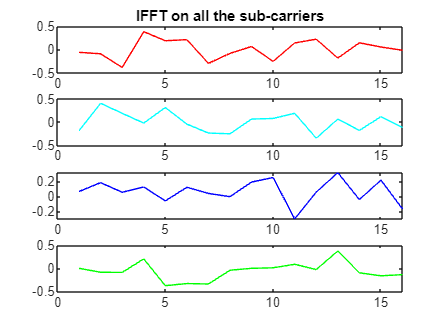

ifft_Subcarrier2 = ifft(Sub_carrier2);
ifft_Subcarrier3 = ifft(Sub_carrier3);
ifft_Subcarrier4 = ifft(Sub_carrier4);

subplot(4,1,1),plot(real(ifft_Subcarrier1),'r'),title('IFFT on all the sub-carriers')
subplot(4,1,2),plot(real(ifft_Subcarrier2),'c')
subplot(4,1,3),plot(real(ifft_Subcarrier3),'b')
subplot(4,1,4),plot(real(ifft_Subcarrier4),'g')

## Step 7: ADD-CYCLIC PREFIX

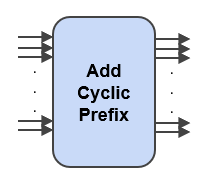

This code snippet is used to add a cyclic prefix to each subcarrier of an OFDM signal. The ifft is used to transform the signal from frequency domain to time domain. The cyclic prefix is added to the beginning of the signal to avoid inter-symbol interference. The prefix is added by copying the last few samples of the signal and appending it to the beginning. This code uses the variable cp_start to specify which samples of the signal should be copied and appended. After the cyclic prefix has been added to each subcarrier, the signal is plotted for each subcarrier.

for i=1:number_of_subcarriers,
ifft_Subcarrier(:,i) = ifft((S2P(:,i)),block_size);% 16 is the ifft point
for j=1:cp_len,
cyclic_prefix(j,i) = ifft_Subcarrier(j+cp_start,i);
end
Append_prefix(:,i) = vertcat( cyclic_prefix(:,i), ifft_Subcarrier(:,i));
% Appends prefix to each subcarriers
end
A1=Append_prefix(:,1)

A1 =   -0.0180 - 0.2067i
  -0.0625 - 0.0625i
  -0.0951 - 0.0338i
  -0.3902 + 0.1768i
   0.3834 - 0.0912i
   0.1875 + 0.0625i
   0.2106 + 0.0817i
  -0.3018 + 0.0884i
  -0.0856 - 0.0433i
   0.0625 - 0.1875i


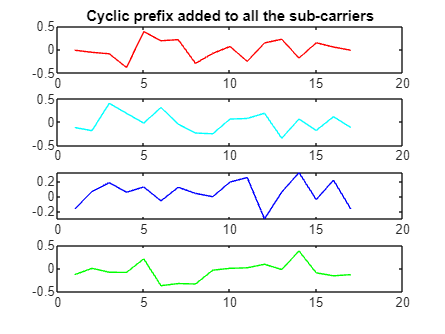

A2=Append_prefix(:,2);
A3=Append_prefix(:,3);
A4=Append_prefix(:,4);
%figure(5), 
subplot(4,1,1),plot(real(A1),'r');title('Cyclic prefix added to all the sub-carriers')
subplot(4,1,2),plot(real(A2),'c');
subplot(4,1,3),plot(real(A3),'b');
subplot(4,1,4),plot(real(A4),'g');

## Step 7: Convert to serial stream for transmission

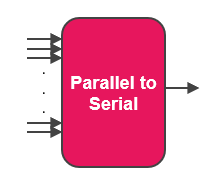

This code is used to form the transmitted signal in serial shape. The data is reshaped into a vector with one row . 

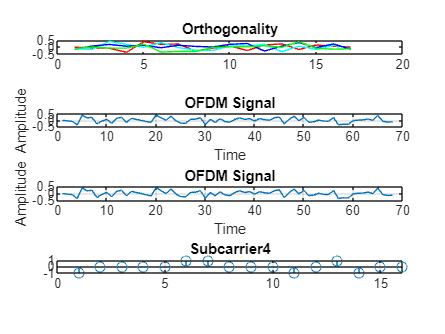


[rows_Append_prefix cols_Append_prefix]=size(Append_prefix);
len_ofdm_data = rows_Append_prefix*cols_Append_prefix;
ofdm_signal = reshape(Append_prefix, 1, len_ofdm_data);
plot(real(ofdm_signal)); xlabel('Time'); ylabel('Amplitude');title('OFDM Signal');grid on;
subplot(4,1,1)
plot((real(A1)),'r'),title('Orthogonality'),hold on 
plot((real(A2)),'c')
plot((real(A3)),'b')
plot((real(A4)),'g'),hold off

subplot(4,1,2),
plot(real(ofdm_signal)); xlabel('Time'); ylabel('Amplitude');
title('OFDM Signal');grid on;

subplot(4,1,3)
plot(real(ofdm_signal)); xlabel('Time'); ylabel('Amplitude');
title('OFDM Signal');grid on;
subplot(4,1,4),stem(real(Sub_carrier4)),title('Subcarrier4'),grid on;

# **Part B: Channel**

## Step 1: Passing time domain data through  AWGN channel

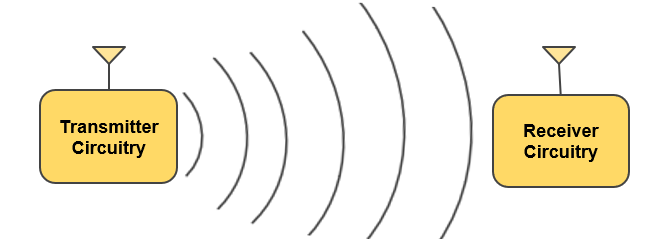

Channel AWGN (Additive White Gaussian Noise) is a channel model used in telecommunications systems. It is a random process that adds a certain amount of noise to a signal as it is transmitted through a channel. The noise added is usually modeled as a zero-mean Gaussian random variable with a particular variance. The noise variance determines the resulting signal's signal-to-noise ratio (SNR). Channel AWGN is widely used in digital communications systems because it is relatively simple to analyze and model. It is also helpful in studying the effects of noise on a communication system, such as interference or fading. By understanding the effects of noise on a signal, engineers can design more robust and reliable systems. Channel AWGN can also be used to simulate the effects of a real-world channel on a signal. This can be useful for testing the performance of a communication system in different environments. Channel AWGN is an essential model for analyzing and designing digital communications systems. It is simple yet powerful enough to accurately simulate real-world channels and noise, making it a valuable tool for engineers.

channel = randn(1,2) + sqrt(-1)*randn(1,2);
after_channel = filter(channel, 1, ofdm_signal);
awgn_noise = awgn(zeros(1,length(after_channel)),0);

# **Part C: Reciver**

## Step 8: Recived Signal

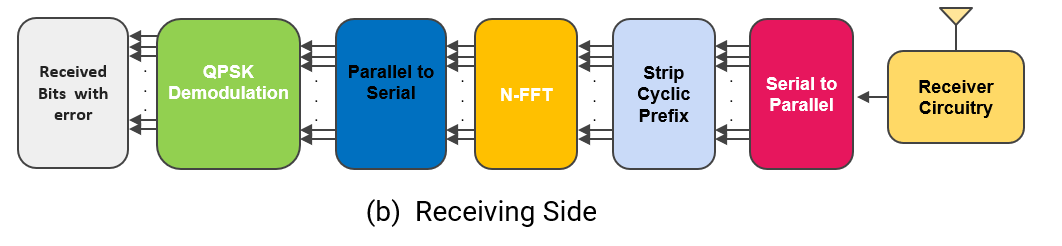

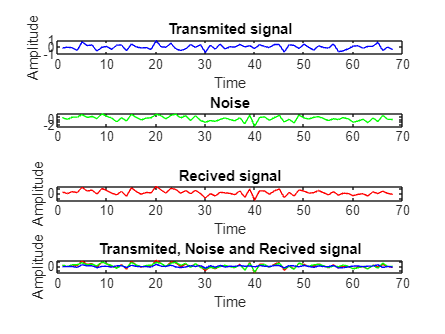

recvd_signal = awgn_noise+after_channel; 

subplot(4,1,1),plot(real(after_channel),'b'),xlabel('Time'); ylabel('Amplitude');title('Transmited signal')
subplot(4,1,2),plot(real(awgn_noise),'g');title('Noise')
subplot(4,1,3),plot(real(recvd_signal),'r'),xlabel('Time'); ylabel('Amplitude');title('Recived signal')

subplot(4,1,4)
plot(real(recvd_signal),'r'),xlabel('Time'); ylabel('Amplitude');hold on
plot(real(awgn_noise),'g')
plot(real(after_channel),'b')
title('Transmited, Noise and Recived signal')
hold off

## Step 2: Converting the series data  into parallel data 

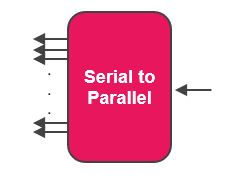

recvd_signal_paralleled = reshape(recvd_signal,rows_Append_prefix, cols_Append_prefix);

## step 3: Remove cyclic Prefix

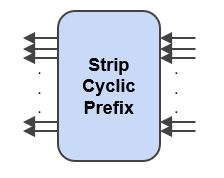

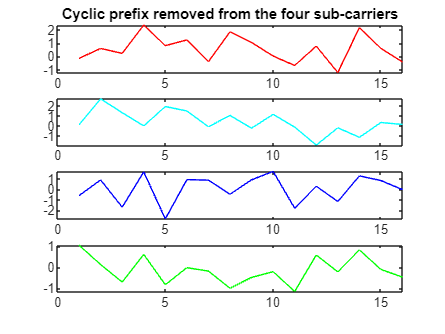

recvd_signal_paralleled(1:cp_len,:)=[];
R1=recvd_signal_paralleled(:,1);
R2=recvd_signal_paralleled(:,2);
R3=recvd_signal_paralleled(:,3);
R4=recvd_signal_paralleled(:,4);

subplot(4,1,1),plot(real(R1),'r'),
title('Cyclic prefix removed from the four sub-carriers')
subplot(4,1,2),plot(real(R2),'c')
subplot(4,1,3),plot(real(R3),'b')
subplot(4,1,4),plot(real(R4),'g')

## Step 3: Converting the Data to Time Domain

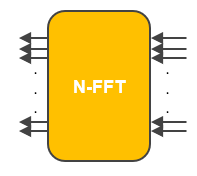

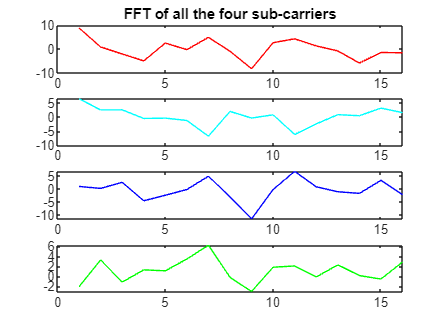

for i=1:number_of_subcarriers,
fft_data(:,i) = fft(recvd_signal_paralleled(:,i),16);
end
F1=fft_data(:,1);
F2=fft_data(:,2);
F3=fft_data(:,3);
F4=fft_data(:,4);
figure(9), subplot(4,1,1),plot(real(F1),'r'),title('FFT of all the four sub-carriers')
subplot(4,1,2),plot(real(F2),'c')
subplot(4,1,3),plot(real(F3),'b')
subplot(4,1,4),plot(real(F4),'g')

## Step 5: Conversion to serial 

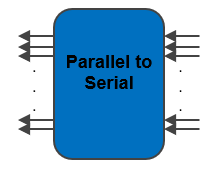

recvd_serial_data = reshape(fft_data, 1,(16*4));

## Step 6: QPSK Demodulation

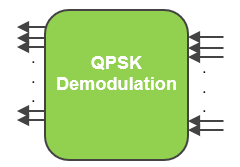

qpsk_demodulated_data = pskdemod(recvd_serial_data,4);

## Step 7: Recived Data with Erorr

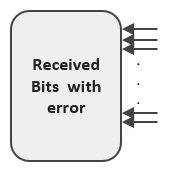

Recived_Data_with_Erorr=qpsk_demodulated_data;

## Step 8: Plot Transmited Data and Recived Data

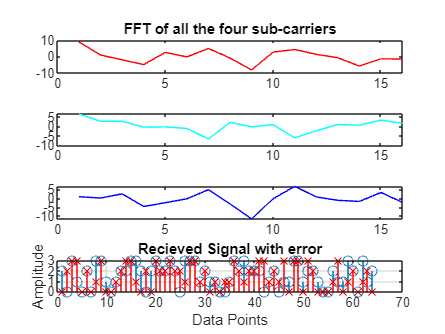

stem(data)
hold on
stem(qpsk_demodulated_data,'rx');
grid on;xlabel('Data Points');ylabel('Amplitude');
title('Recieved Signal with error')
hold off

## Step 9: Plot Bet Error Rate for the System

Bet Error Rate (BER) is a measure of the accuracy of a communication system, usually expressed as a percentage. It is calculated by dividing the number of errors that occur in a transmission by the total number of bits that are sent. Bet Error Rate is used to measure the effectiveness of communication systems, such as modems, wireless networking, and satellite communications. It is an important metric for determining the quality of service being provided and can help identify potential problems with a system. BER can be used to compare different systems and to measure the impact of any changes that are made to the system.